% Initialize values
clear;clc;
TR = 100;
T2_dephasing = 50;
n=901;
Alpha = linspace(0,pi/2,n);

% Calculate Mz
T1 = [1000 1100]

T1 =         1000        1100


% for T1_1
Mz(1,:) = ((1-exp(-TR/T1(1))).*sin(Alpha))./(1-exp(-TR/T1(1)).*cos(Alpha)); 

% for T1_2
Mz(2,:) = ((1-exp(-TR/T1(2))).*sin(Alpha))./(1-exp(-TR/T1(2)).*cos(Alpha)); 

% Find maximum MRI image brightness difference between the two tissues(T1s)
different = abs(Mz(2,:)-Mz(1,:));
index = find(different == max(different));
maxAngle = Alpha(index)*180/pi

maxAngle = 41.4000

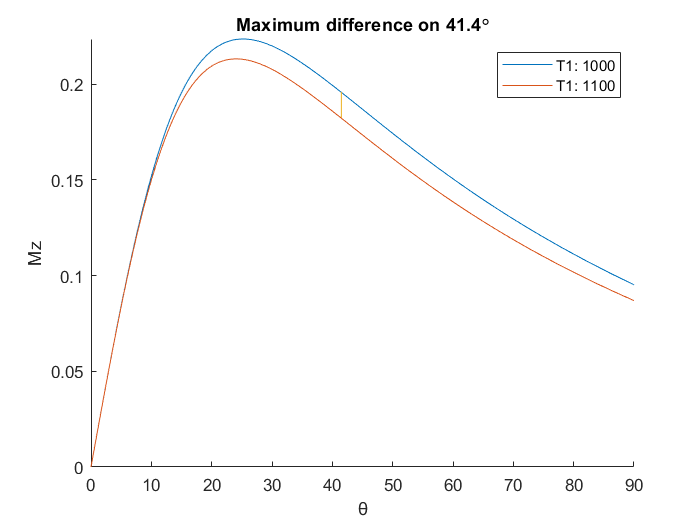

% Show the result
figure();
hold on
plot(Alpha*180/pi,Mz(1,:))
plot(Alpha*180/pi,Mz(2,:))
plot([index/10 index/10],Mz(:,index))
txt = ['Maximum difference on ',num2str(maxAngle),'\circ'];
xlabel("θ")
ylabel("Mz")
title(txt)
legend([strcat("T1: ",num2str(T1(1))); strcat("T1: ",num2str(T1(2)))])
axis([0 90 min(Mz(:)) max(Mz(:))])